#### AERO50003

#### Introduction to Numerical Methods for ODEs and PDEs

### **Tutorial Sheet 2**

## Finite Differences

Masoud Seifikar

Autumn Term 2023

Department of Aeronautics, Imperial College London 

### Part I: Practical Exercises

#### Exercise 1 (Explicit Euler to solve the model problem)

Consider the model problem

y′ = λy , y(0) = y0 .

We wish to obtain the solution y(t) of this initial value problem from the initial time t = 0 to the final time t = tf . Write a code to implement Explicit Euler, i.e.

yn+1 = yn + hy′n = yn + hλyn ,

where h is the step size.

1. What is the exact solution ˜y(t) of the problem (in terms of λ)?

% y (t) = y0 * exp(λt)

2. Select any initial condition y0. Suppose λ = −1 and let tf = 25. In the following we will compare the effect of different step sizes on the performance of explicit Euler for this problem. You may wish to plot the exact solution ˜y(t) along with the numerical solutions for comparison.

(a) What is the maximum stepsize hmax possible to ensure numerical stability?

% Housekeeping
clear
clc
close all

% Define the basic parameters
y0 = 0.1;  % define the initial condition
lamb = -1; % define the lambda
t0 = 0;    % define the initial time
tf = 25;   % define the final time

% Calculate maximum stepsize
hmax = 2 / abs(lamb); % hmax = 2 / |λR|
R = [' The maximum stepsize possible to ensure numerical stability is ', num2str(hmax), '.'];
disp(R)

 The maximum stepsize possible to ensure numerical stability is 2.


(b) Using explicit Euler, compute and plot (as a function of time) the numerical solution with h = hmax.

(c) Using explicit Euler, compute and plot (as a function of time) the numerical solution with h = hmax/2.

(d) Using explicit Euler, compute and plot (as a function of time) the numerical solution with h = hmax + 0.1.

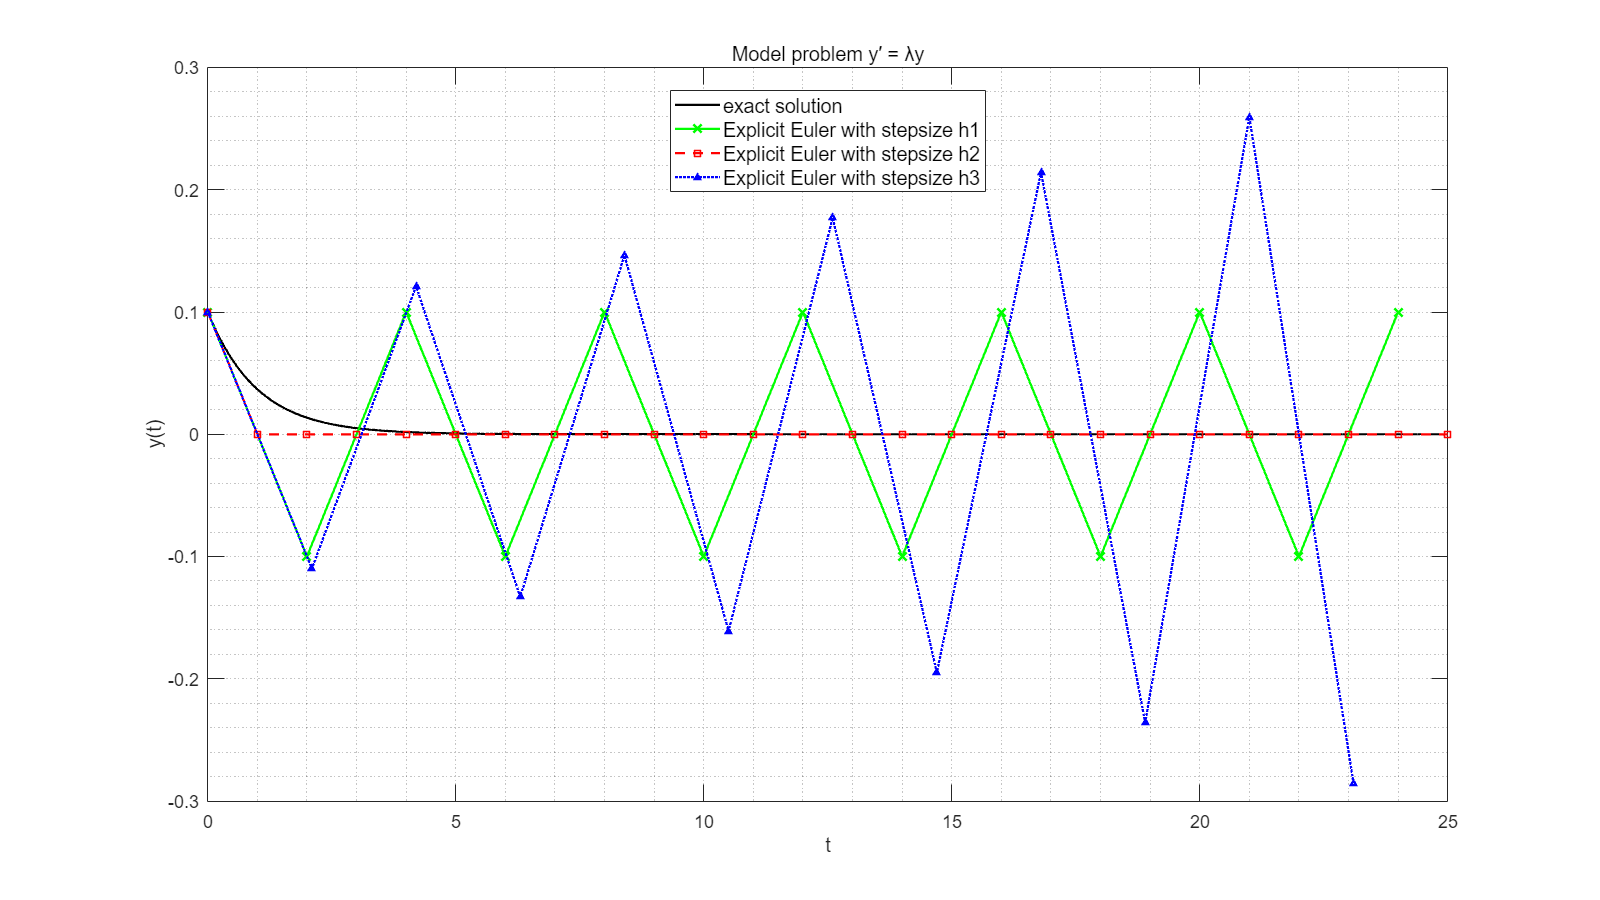

% Define the stepsize
h1 = hmax;       % define the maximum stepsize
h2 = hmax / 2;   % define the half maximum stepsize
h3 = hmax + 0.1; % define the half maximum stepsize

% Compute the exact solution
t = t0 : 0.001 : tf; % define the t for exact solution
y = y0 * exp(lamb * t);

% Compute the numerical solution
t1 = t0 : h1 : tf; % define the t for h1
t2 = t0 : h2 : tf; % define the t for h2
t3 = t0 : h3 : tf; % define the t for h3

y1 = zeros(1, length(t1)); % create empty matrix to store data for h1
y2 = zeros(1, length(t2)); % create empty matrix to store data for h2
y3 = zeros(1, length(t3)); % create empty matrix to store data for h3

y1(1) = y0; % define the starting point for y1
y2(1) = y0; % define the starting point for y2
y3(1) = y0; % define the starting point for y3

for i = 1 : length(t1) - 1

    y1(i + 1) = y1(i) + h1 * lamb * y1(i); % calculate Explicit Euler for h1

end

for i = 1 : length(t2) - 1

    y2(i + 1) = y2(i) + h2 * lamb * y2(i); % calculate Explicit Euler for h2

end

for i = 1 : length(t3) - 1

    y3(i + 1) = y3(i) + h3 * lamb * y3(i); % calculate Explicit Euler for h3

end

% Plot the numerical solutions and compare with the exact solution
plot(t, y, 'k', LineWidth = 1.5);                      % plot exact solution 
hold on
plot(t1, y1, '-xg', LineWidth = 1.5, MarkerSize = 8);  % plot Explicit Euler with stepsize h1
hold on
plot(t2, y2, '--sr', LineWidth = 1.5, MarkerSize = 5); % plot Explicit Euler with stepsize h2
hold on
plot(t3, y3, ':^b', LineWidth = 1.5, MarkerSize = 3);  % plot Explicit Euler with stepsize h2
hold off

title('Model problem y′ = λy', FontSize = 15);
legend('exact solution', 'Explicit Euler with stepsize h1', 'Explicit Euler with stepsize h2', ...
    'Explicit Euler with stepsize h3', 'Location', 'Best', FontSize = 13)

xlabel('t'); 
ylabel('y(t)');
set(gca, 'FontSize', 12) % set the fontsize of the axis

grid minor;                            % set the grid of the graph
set(gcf, 'Position', [0 0 1920 1080]); % show plot with larger size

(e) For each of the step sizes, plot the global error |yn − ˜y(tn)| as a function of the time step.

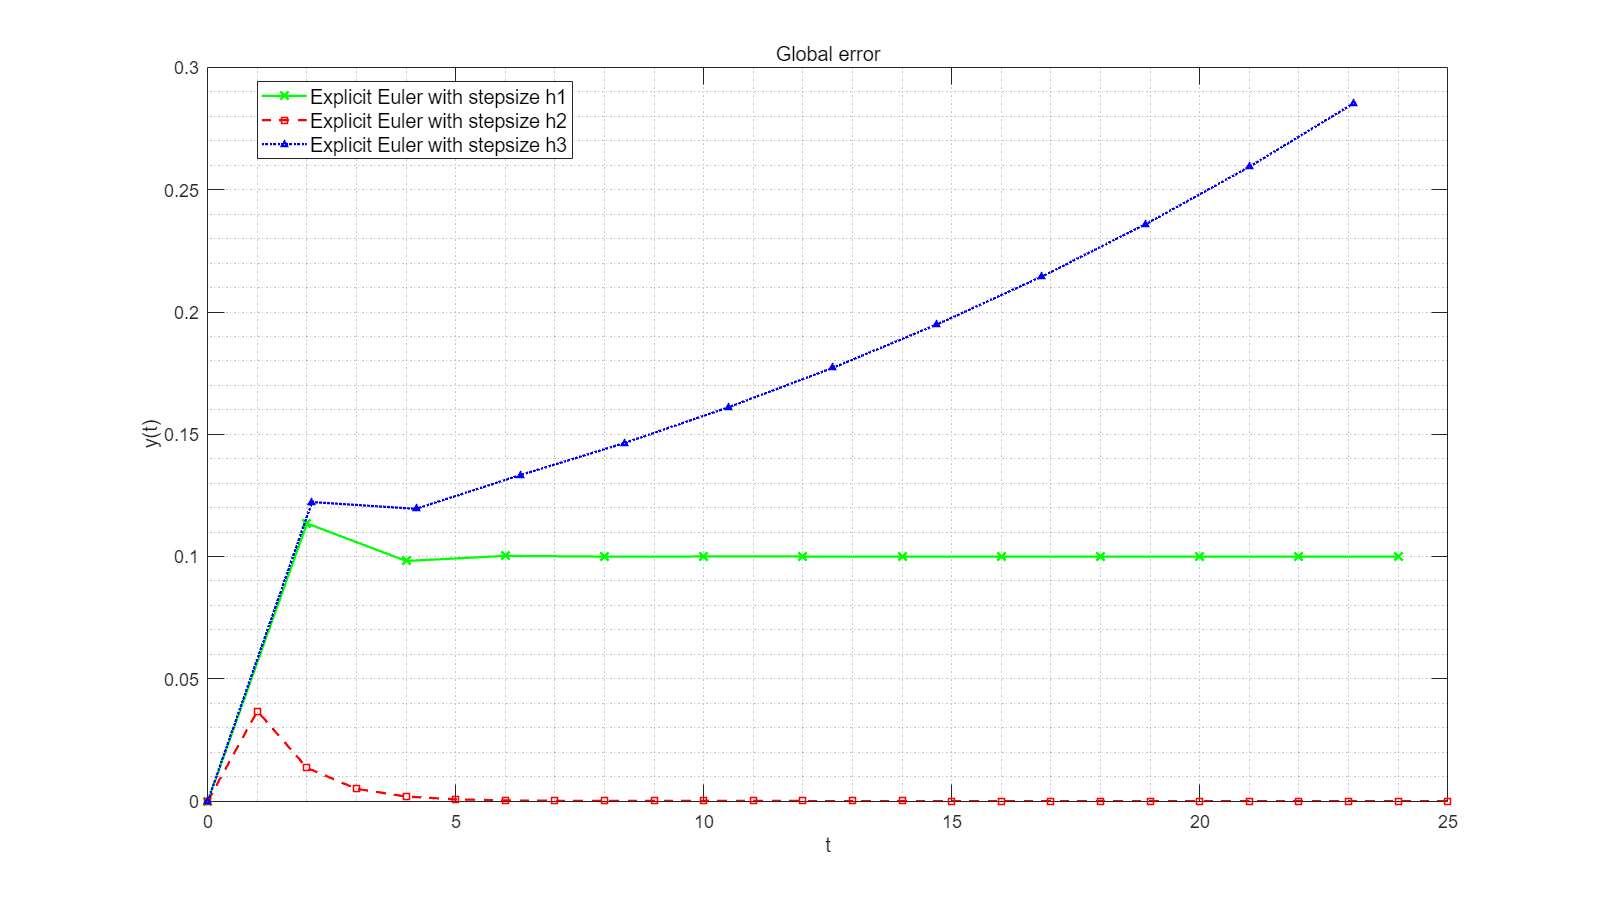

% Calculate the global error
ey1 = abs(y0 * exp(lamb * t1) - y1);
ey2 = abs(y0 * exp(lamb * t2) - y2);
ey3 = abs(y0 * exp(lamb * t3) - y3);

% Plot the global error
plot(t1, ey1, '-xg', LineWidth = 1.5, MarkerSize = 8);  % plot global error for Explicit Euler with stepsize h1
hold on
plot(t2, ey2, '--sr', LineWidth = 1.5, MarkerSize = 5); % plot global error for Explicit Euler with stepsize h2
hold on
plot(t3, ey3, ':^b', LineWidth = 1.5, MarkerSize = 3);  % plot global error for Explicit Euler with stepsize h2
hold off

title('Global error', FontSize = 15);
legend('Explicit Euler with stepsize h1', 'Explicit Euler with stepsize h2', ...
    'Explicit Euler with stepsize h3', 'Location', 'Best', FontSize = 13)

xlabel('t'); 
ylabel('y(t)');
set(gca, 'FontSize', 12) % set the fontsize of the axis

grid minor; % set the grid of the graph

(f ) Comment on the numerical stability of explicit Euler for the different choices of h.

% for h1 = hmax, numerical stable.
% for h2 = hmax / 2, numerical stable.
% for h3 = hmax + 0.1, numerical unstable.

(g) Compare the accuracy achieved for each selection of h. What is the cost of improved accuracy?

% h2 = hmax / 2 is more accurate than h1 = hmax which both are numerical
% stable. However, computational power required by h2 is larger.

3. Suppose λ = iλI is purely imaginary.

(a) For some value of λ (you pick!), use explicit Euler to see (as we demonstrated in the lecture) that this particular numerical method is unstable for purely imaginary λ.

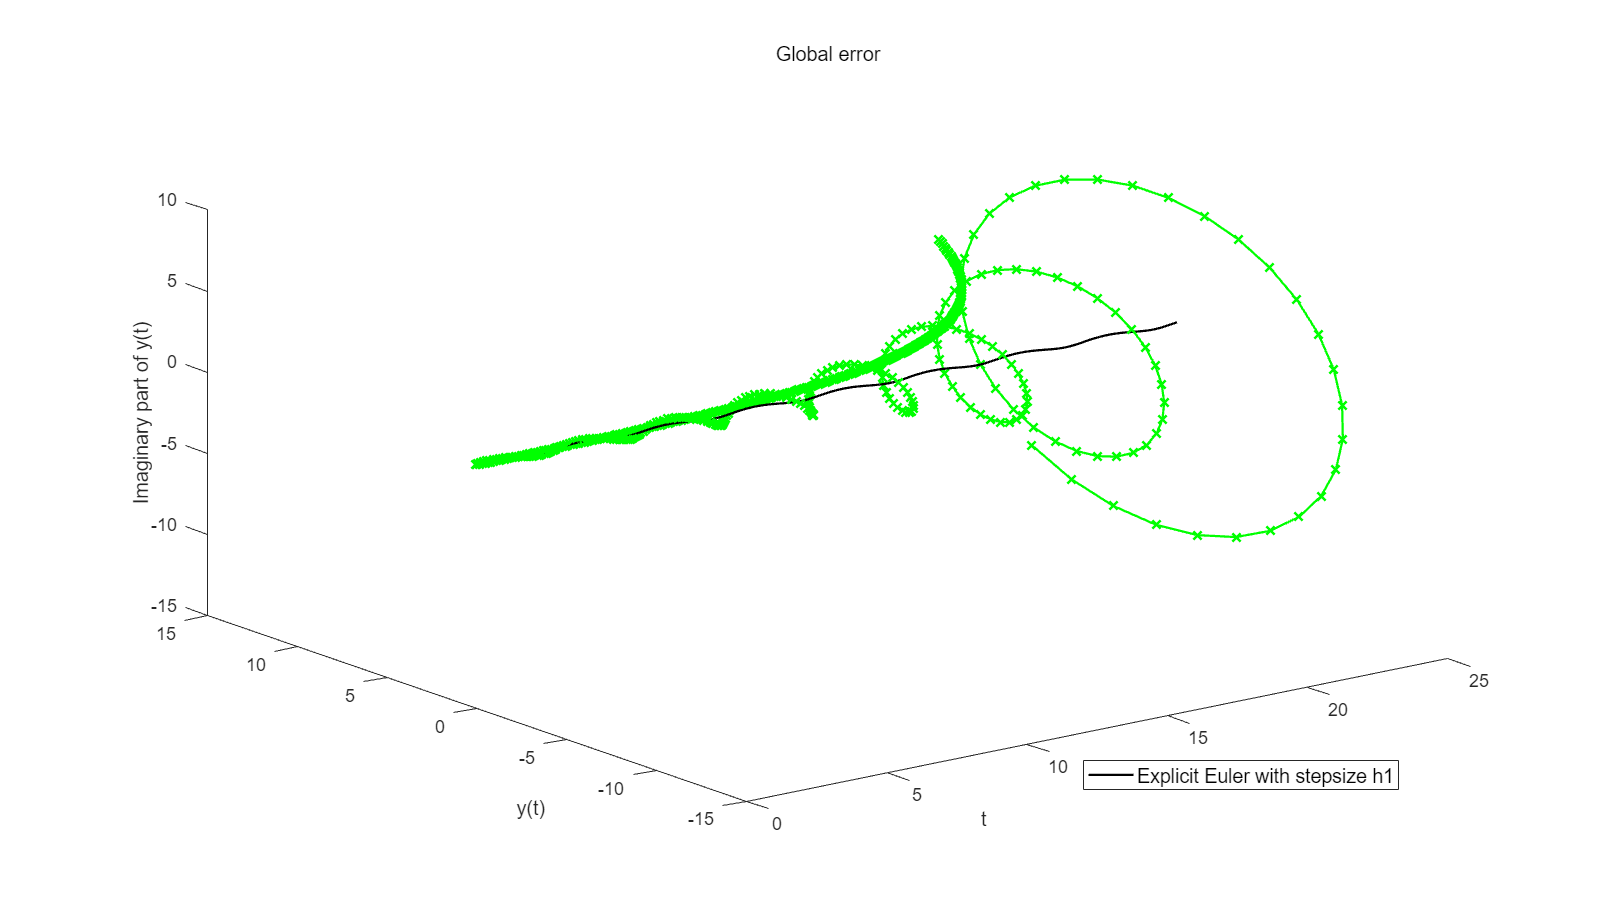

% Housekeeping
clear
clc

% Define the basic parameters
y0 = 0.1;  % define the initial condition
lamb = 2i; % define the lambda
t0 = 0;    % define the initial time
tf = 25;   % define the final time
h1 = 0.1;    % define the stepsize 1

% Compute the exact solution
t = t0 : 0.001 : tf; % define the t for exact solution
y = y0 * exp(lamb * t);

% Compute the numerical solution
t1 = t0 : h1 : tf; % define the t for h1

y1 = zeros(1, length(t1)); % create empty matrix to store data for h1

y1(1) = y0; % define the starting point for y1

for i = 1 : length(t1) - 1

    y1(i + 1) = y1(i) + h1 * lamb * y1(i); % calculate Explicit Euler for h1

end

% Plot the numerical solutions and compare with the exact solution
plot3(t, real(y), imag(y), 'k', LineWidth = 1.5);                       % plot exact solution 
hold on
plot3(t1, real(y1), imag(y1), '-xg', LineWidth = 1.5, MarkerSize = 8);  % plot Explicit Euler with stepsize h1
hold on

title('Model problem y′ = λy', FontSize = 15);
legend('exact solution', 'Explicit Euler with stepsize h1', 'Location', 'Best', FontSize = 13)

xlabel('t'); 
ylabel('Real part of y(t)');
zlabel('Imaginary part of y(t)');
set(gca, 'FontSize', 12) % set the fontsize of the axis

grid minor; % set the grid of the graph
% Calculate the global error
ey1 = abs(y0 * exp(lamb * t1) - y1);

% Plot the global error
plot(t1, ey1, '-xg', LineWidth = 1.5, MarkerSize = 8);  % plot global error for Explicit Euler with stepsize h1

title('Global error', FontSize = 15);
legend('Explicit Euler with stepsize h1', 'Location', 'Best', FontSize = 13)

xlabel('t'); 
ylabel('y(t)');
set(gca, 'FontSize', 12) % set the fontsize of the axis

grid minor; % set the grid of the graph

#### Exercise 2 (Improved performance by including higher order derivatives)

Consider again the model problem

y′ = λy , y(0) = y0 .

Instead of using explicit Euler, we wish to include the second derivative in the Taylor series expansion of yn+1 about t = tn in the hope of getting a more accurate numerical method.

1. Derive the numerical method for solving the model problem, which includes the second derivative y′′ in the Taylor series expansion of yn about t = tn.

% yn+1 = yn + hy'n + (h ^ 2 / 2) * y''n = yn + hλyn + (h ^ 2 / 2) (λ ^ 2
% yn) = (1 + hλ + (hλ)^2/2)yn

2. Assess the stability properties of the numerical scheme.

% σ = 1 + hλ + (hλ)^2/2
% Conditionally stable numerical scheme

3. What is the order of the local error of this scheme?

% 3rd.

4. What is the order of the global error of this scheme?

% 2nd.

5. Let λ = −1 and tf = 25. Writing your own code or using the code provided, for some time step h, plot the numerical solution and compare it to the numerical solution achieved using explicit Euler in the previous exercise.

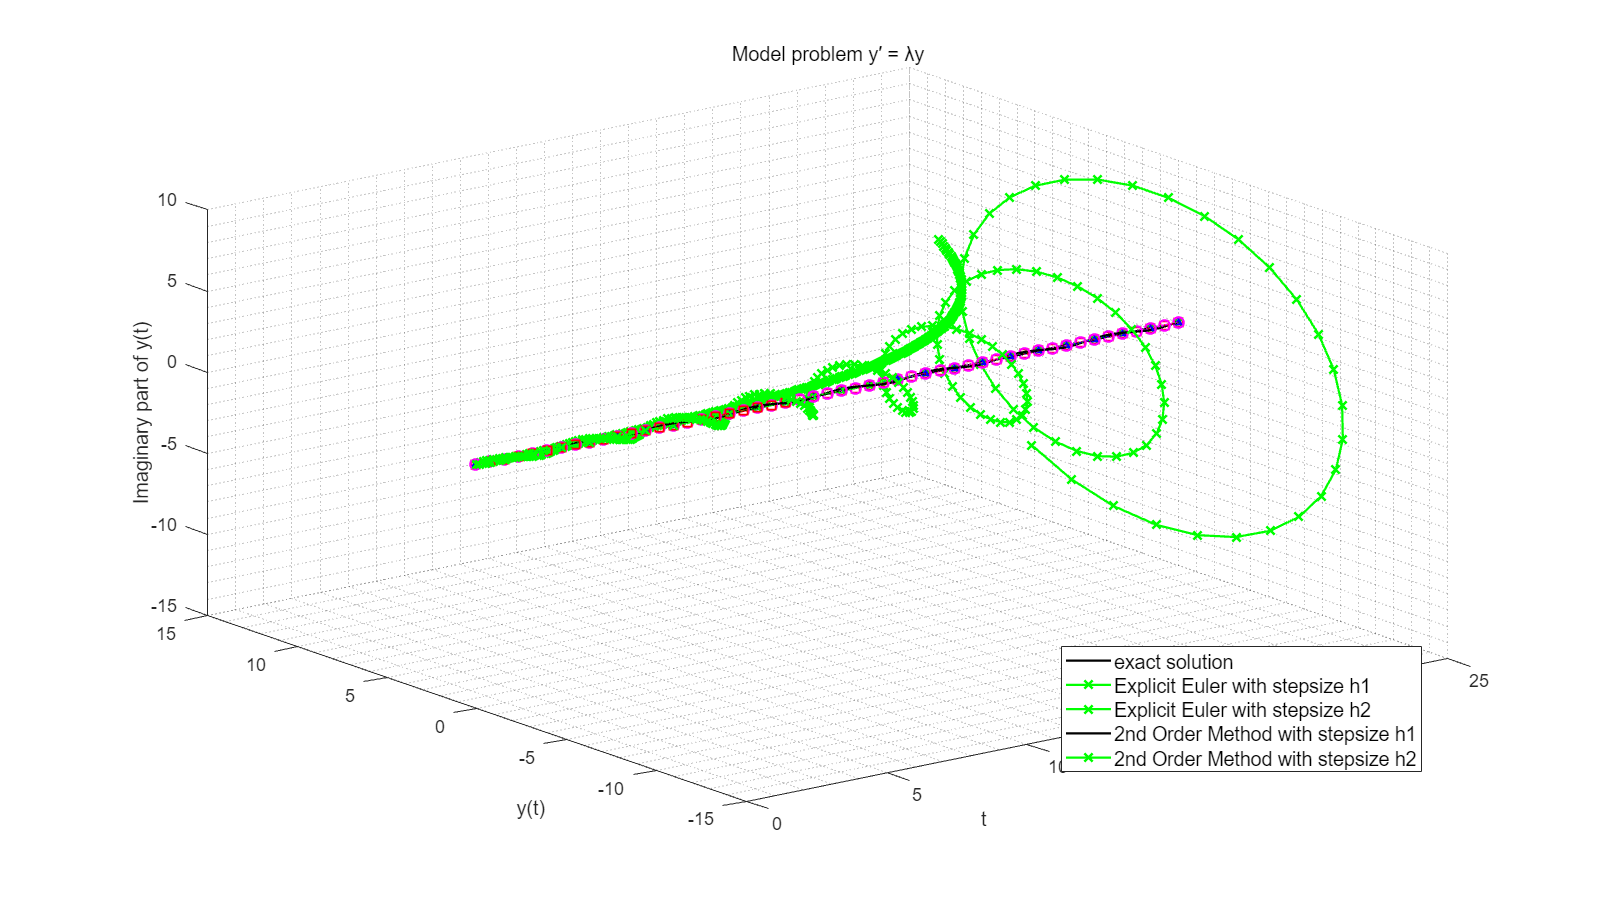

% Housekeeping
clear
clc

% Define the basic parameters
y0 = 0.1;  % define the initial condition
lamb = -1; % define the lambda
t0 = 0;    % define the initial time
tf = 25;   % define the final time
h1 = 1;    % define the stepsize 1
h2 = 0.5;  % define the stepsize 2

% Compute the exact solution
t = t0 : 0.001 : tf; % define the t for exact solution
y = y0 * exp(lamb * t);

% Compute the numerical solution
t1 = t0 : h1 : tf; % define the t for h1
t2 = t0 : h2 : tf; % define the t for h2

y1 = zeros(1, length(t1)); % create empty matrix to store data for Explicit h1
y2 = zeros(1, length(t2)); % create empty matrix to store data for Explicit h2
y3 = y1;                   % create empty matrix to store data for 2nd Order h1
y4 = y2;                   % create empty matrix to store data for 2nd Order h2

y1(1) = y0; % define the starting point for y1
y2(1) = y0; % define the starting point for y2
y3(1) = y0; % define the starting point for y3
y4(1) = y0; % define the starting point for y3

for i = 1 : length(t1) - 1

    y1(i + 1) = y1(i) + h1 * lamb * y1(i); % calculate Explicit Euler for h1

end

for i = 1 : length(t2) - 1

    y2(i + 1) = y2(i) + h2 * lamb * y2(i); % calculate Explicit Euler for h2

end

for i = 1 : length(t1) - 1

    y3(i + 1) = y3(i) * (1 + h1 * lamb + (h1 * lamb) ^ 2 / 2); % calculate 2nd Order Method for h1

end

for i = 1 : length(t2) - 1

    y4(i + 1) = y4(i) * (1 + h2 * lamb + (h2 * lamb) ^ 2 / 2); % calculate 2nd Order Method for h2

end

% Plot the numerical solutions and compare with the exact solution
plot(t, y, 'k', LineWidth = 1.5);                      % plot exact solution 
hold on
plot(t1, y1, '-xg', LineWidth = 1.5, MarkerSize = 8);  % plot Explicit Euler with stepsize h1
hold on
plot(t2, y2, '--sr', LineWidth = 1.5, MarkerSize = 7); % plot Explicit Euler with stepsize h2
hold on
plot(t1, y3, ':^b', LineWidth = 1.5, MarkerSize = 3);  % plot 2nd Order Method with stepsize h1
hold on
plot(t2, y4, ':om', LineWidth = 1.5, MarkerSize = 7);  % plot 2nd Order Method with stepsize h2
hold off

title('Model problem y′ = λy', FontSize = 15);
legend('exact solution', 'Explicit Euler with stepsize h1', 'Explicit Euler with stepsize h2', ...
    '2nd Order Method with stepsize h1', '2nd Order Method with stepsize h2', 'Location', 'Best', FontSize = 13)

xlabel('t'); 
ylabel('y(t)');
set(gca, 'FontSize', 12) % set the fontsize of the axis

grid minor; % set the grid of the graph

#### **Exercise 3 (Implicit Euler to solve the model problem)**

Consider again the model problem

y′ = λy , y(0) = y0 .

Write code to implement implicit Euler, i.e.

yn+1 = yn + hf(tn+1, yn+1) = yn + hλyn+1 .

1. Assess the numerical stability of this scheme for the model problem.

% σ = (1 + hλ/2) / (1 - hλ/2)
% Unconditionally stable numerical scheme

2. Select an initial condition y0. For λ = −2, we wish to obtain a numerical solution using implicit Euler.

(a) Let tf = 20 and h = 1.1. Plot the numerical solution obtained using implicit Euler. How does the result compare to the numerical solution you would have obtained using explicit Euler with the same parameters?

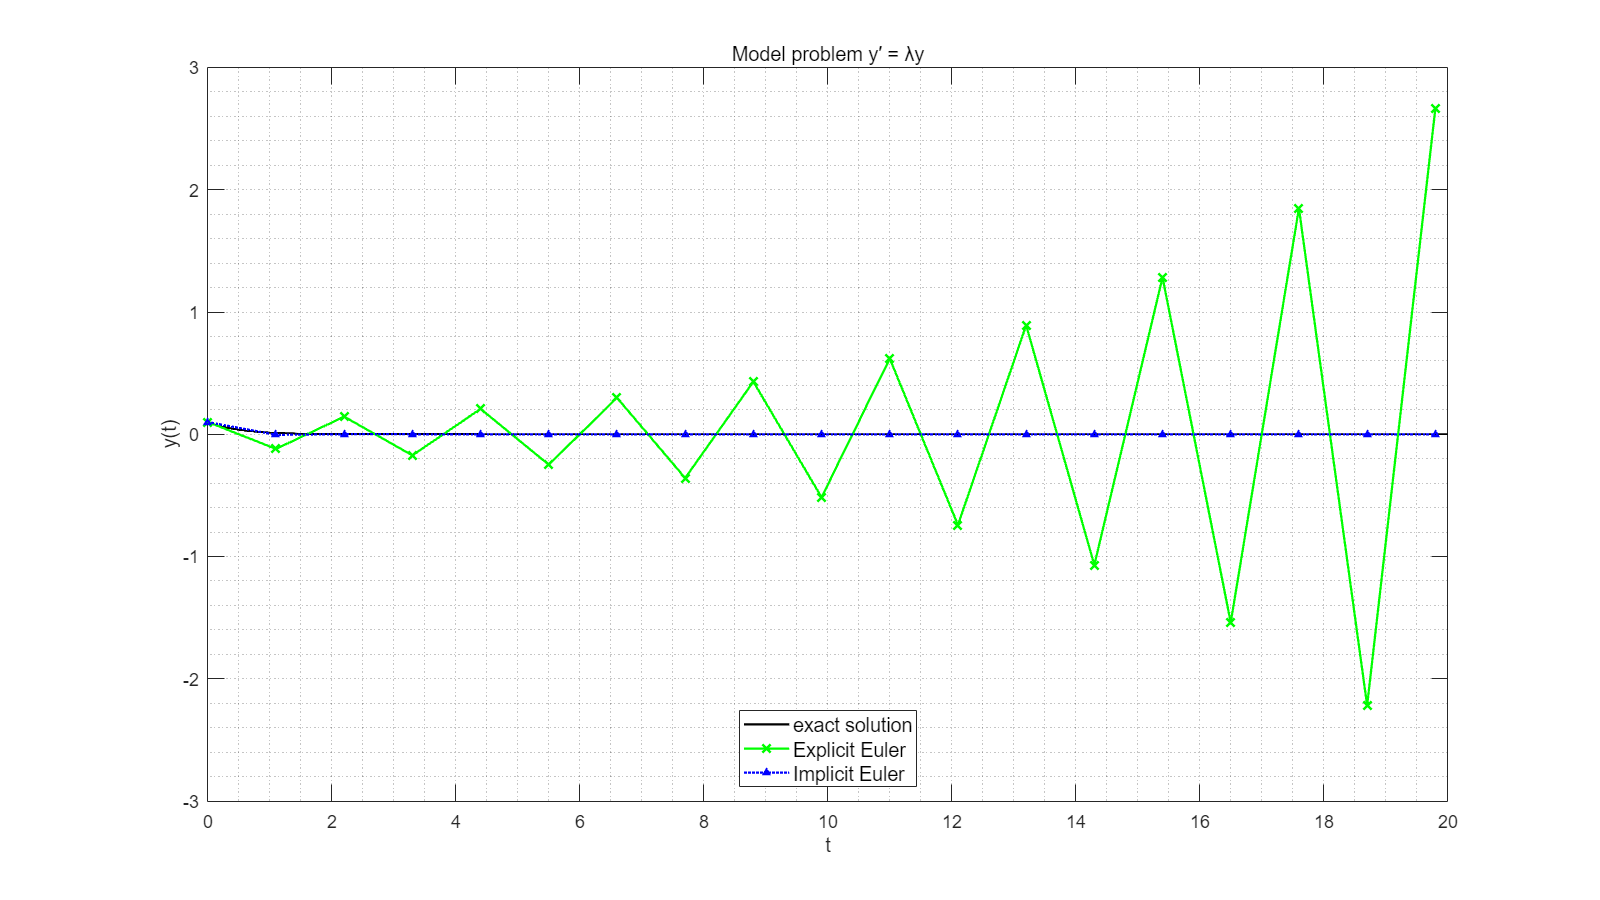

% Housekeeping
clear
clc

% Define the basic parameters
y0 = 0.1;  % define the initial condition
lamb = -2; % define the lambda
t0 = 0;    % define the initial time
tf = 20;   % define the final time
h = 1.1;   % define the stepsize

% Compute the exact solution
t = t0 : 0.001 : tf; % define the t for exact solution
y = y0 * exp(lamb * t);

% Compute the numerical solution
t1 = t0 : h : tf; % define the t for h1

y1 = zeros(1, length(t1)); % create empty matrix to store data for Explicit
y2 = y1;                   % create empty matrix to store data for Implicit

y1(1) = y0; % define the starting point for y1
y2(1) = y0; % define the starting point for y2

for i = 1 : length(t1) - 1

    y1(i + 1) = y1(i) + h * lamb * y1(i);                          % calculate Explicit Euler
    y2(i + 1) = y2(i) * ((1 + h * lamb / 2) / (1 - h * lamb / 2)); % calculate Implicit Euler

end

% Plot the numerical solutions and compare with the exact solution
plot(t, y, 'k', LineWidth = 1.5);                     % plot exact solution 
hold on
plot(t1, y1, '-xg', LineWidth = 1.5, MarkerSize = 8); % plot Explicit Euler
hold on
plot(t1, y2, ':^b', LineWidth = 1.5, MarkerSize = 3); % plot Implicit Euler
hold on
hold off

title('Model problem y′ = λy', FontSize = 15);
legend('exact solution', 'Explicit Euler', 'Implicit Euler', 'Location', 'Best', FontSize = 13)

xlabel('t'); 
ylabel('y(t)');
set(gca, 'FontSize', 12) % set the fontsize of the axis

grid minor; % set the grid of the graph

(b) Let tf = 20 and h = 0.1. Plot the numerical solution obtained using implicit Euler. How does the result compare to the numerical solution obtained (using implicit Euler) in part (a)?

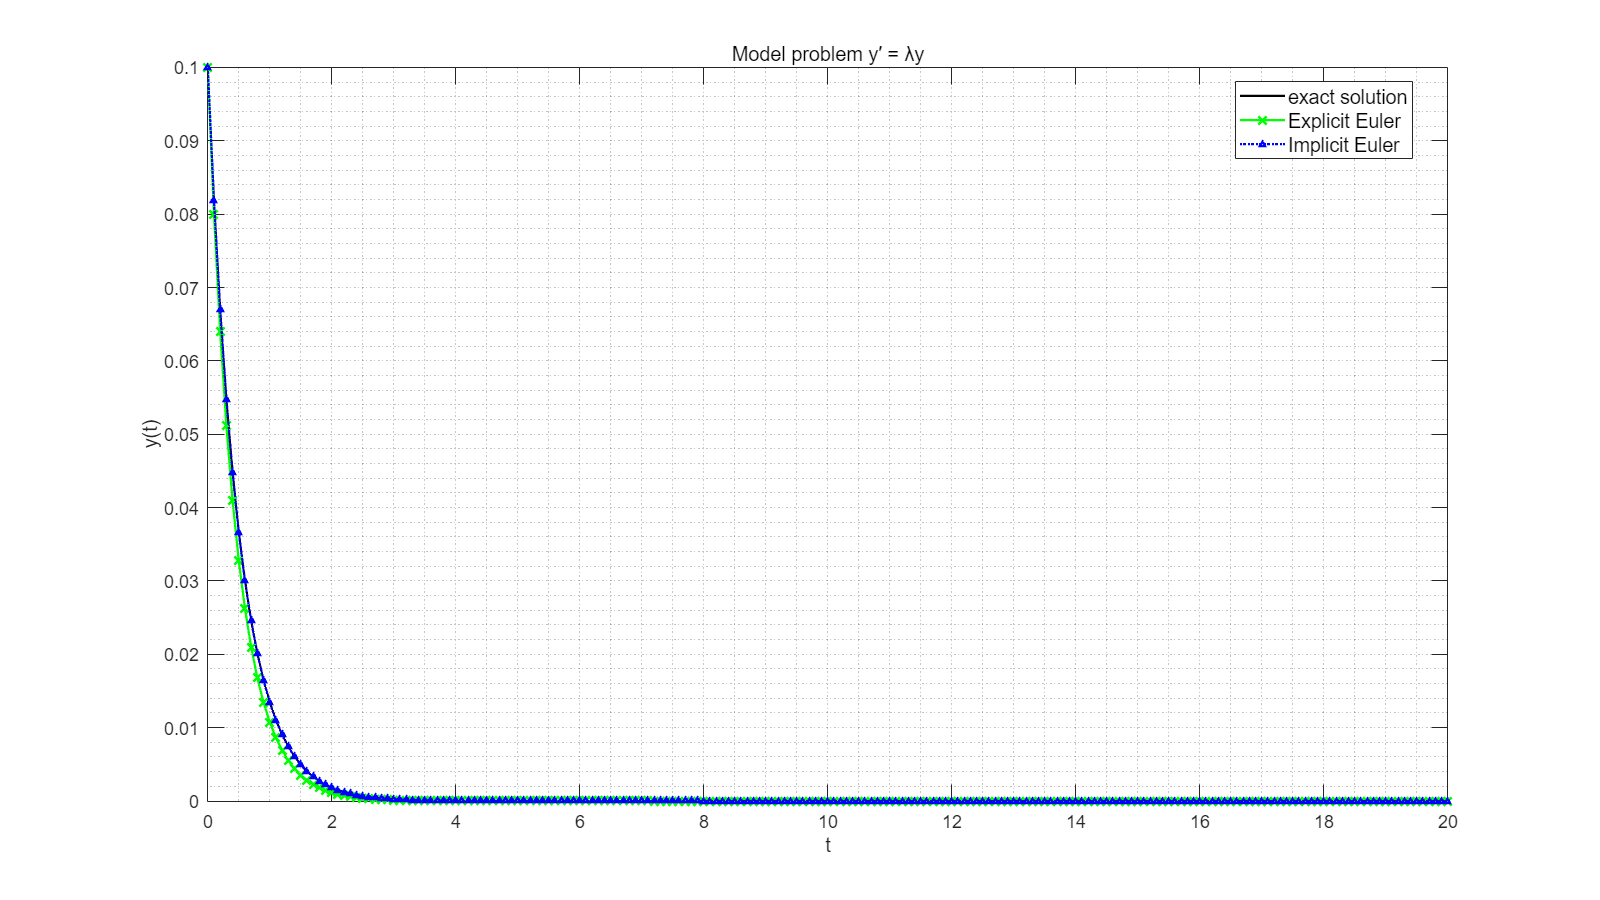

% Housekeeping
clear
clc

% Define the basic parameters
y0 = 0.1;  % define the initial condition
lamb = -2; % define the lambda
t0 = 0;    % define the initial time
tf = 20;   % define the final time
h = 0.1;   % define the stepsize

% Compute the exact solution
t = t0 : 0.001 : tf; % define the t for exact solution
y = y0 * exp(lamb * t);

% Compute the numerical solution
t1 = t0 : h : tf;      % define the t for h1

y1 = zeros(1, length(t1)); % create empty matrix to store data for Explicit
y2 = y1;                   % create empty matrix to store data for Implicit

y1(1) = y0; % define the starting point for y1
y2(1) = y0; % define the starting point for y2

for i = 1 : length(t1) - 1

    y1(i + 1) = y1(i) + h * lamb * y1(i);                          % calculate Explicit Euler
    y2(i + 1) = y2(i) * ((1 + h * lamb / 2) / (1 - h * lamb / 2)); % calculate Implicit Euler

end

% Plot the numerical solutions and compare with the exact solution
plot(t, y, 'k', LineWidth = 1.5);                     % plot exact solution 
hold on
plot(t1, y1, '-xg', LineWidth = 1.5, MarkerSize = 8); % plot Explicit Euler
hold on
plot(t1, y2, ':^b', LineWidth = 1.5, MarkerSize = 3); % plot Implicit Euler
hold on
hold off

title('Model problem y′ = λy', FontSize = 15);
legend('exact solution', 'Explicit Euler', 'Implicit Euler', 'Location', 'Best', FontSize = 13)

xlabel('t'); 
ylabel('y(t)');
set(gca, 'FontSize', 12) % set the fontsize of the axis

grid minor; % set the grid of the graph

3. For λ = i, we wish to obtain a numerical solution using implicit Euler.

(a) Let tf = 20 and h = 1. Plot the numerical solution obtained using implicit Euler.

(b) Let tf = 20 and h = 0.1. Plot the numerical solution obtained using implicit Euler.

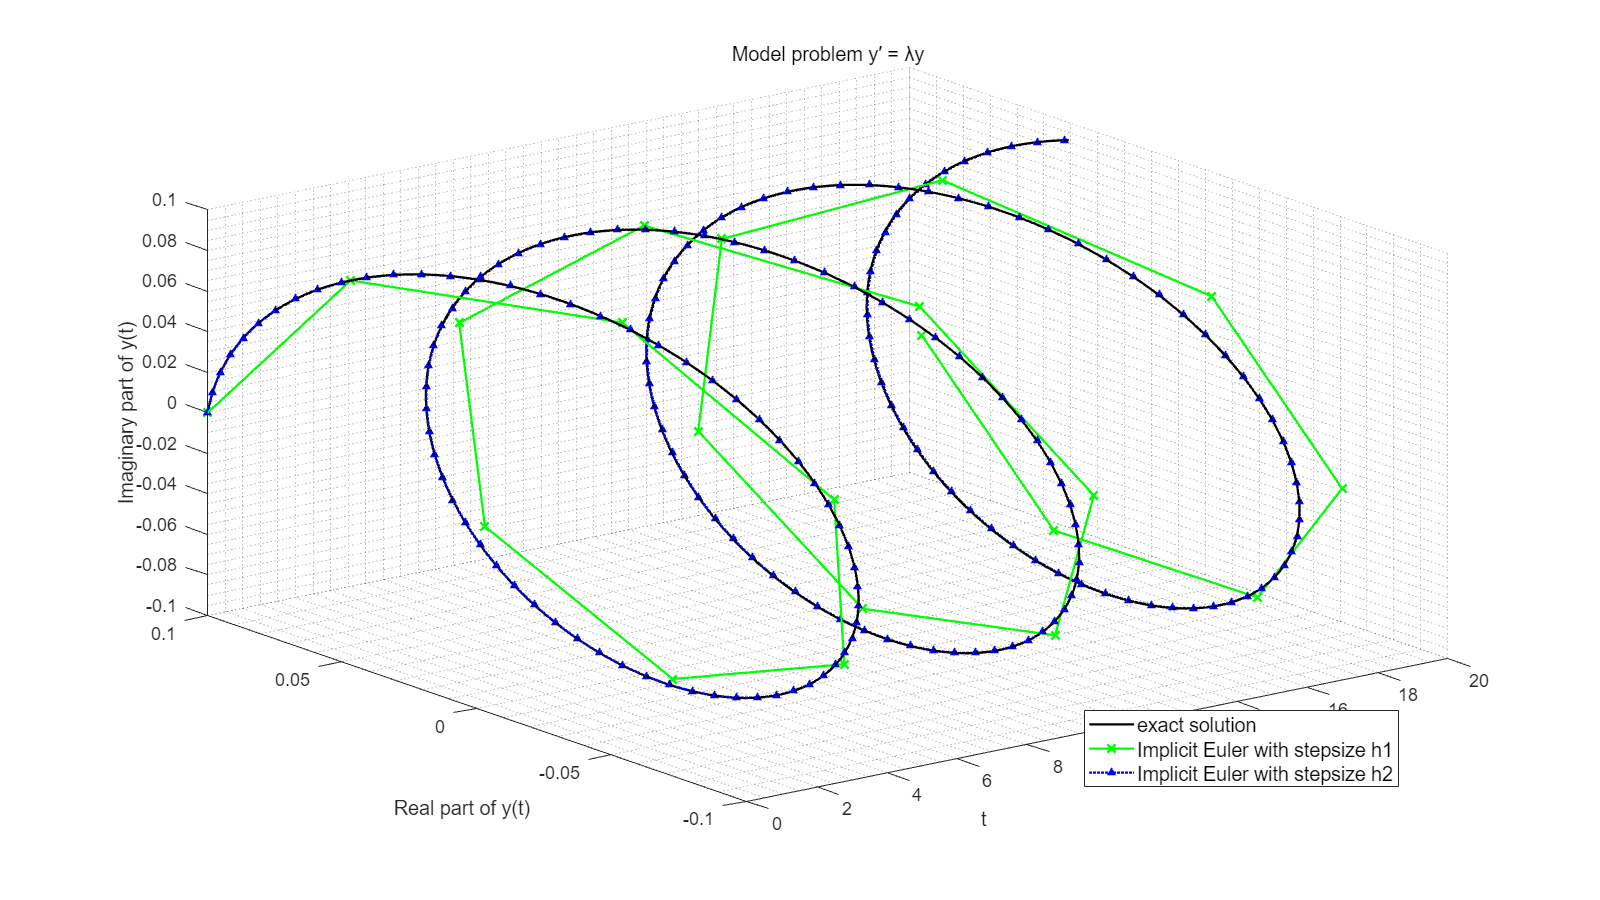

% Housekeeping
clear
clc

% Define the basic parameters
y0 = 0.1;  % define the initial condition
lamb = 1i; % define the lambda
t0 = 0;    % define the initial time
tf = 20;   % define the final time
h1 = 1;    % define the stepsize 1
h2 = 0.1;  % define the stepsize 2

% Compute the exact solution
t = t0 : 0.001 : tf; % define the t for exact solution
y = y0 * exp(lamb * t);

% Compute the numerical solution
t1 = t0 : h1 : tf; % define the t for h1
t2 = t0 : h2 : tf; % define the t for h2

% Compute the numerical solution
y1 = zeros(1, length(t1)); % create empty matrix to store data for Implicit h1
y2 = zeros(1, length(t2)); % create empty matrix to store data for Implicit h2

y1(1) = y0; % define the starting point for y1
y2(1) = y0; % define the starting point for y2

for i = 1 : length(t1) - 1

    y1(i + 1) = y1(i) * ((1 + h1 * lamb / 2) / (1 - h1 * lamb / 2)); % calculate Implicit Euler for h1

end

for i = 1 : length(t2) - 1

    y2(i + 1) = y2(i) * ((1 + h2 * lamb / 2) / (1 - h2 * lamb / 2)); % calculate Implicit Euler for h2

end

% Plot the numerical solutions and compare with the exact solution
plot3(t, real(y), imag(y), 'k', LineWidth = 1.5);                      % plot exact solution 
hold on
plot3(t1, real(y1), imag(y1), '-xg', LineWidth = 1.5, MarkerSize = 8); % plot Implicit Euler with stepsize h1
hold on
plot3(t2, real(y2), imag(y2), ':^b', LineWidth = 1.5, MarkerSize = 3); % plot Implicit Euler with stepsize h2
hold on
hold off

title('Model problem y′ = λy', FontSize = 15);
legend('exact solution', 'Implicit Euler with stepsize h1', 'Implicit Euler with stepsize h2', ...
    'Location', 'Best', FontSize = 13)

xlabel('t'); 
ylabel('Real part of y(t)');
zlabel('Imaginary part of y(t)');
set(gca, 'FontSize', 12) % set the fontsize of the axis

grid minor; % set the grid of the graph

(c) Comment on numerical stability and accuracy of the numerical schemes in parts (a) and (b).

% Both shemes are numerical stable, smaller stepsize gives more accurate
% results but cost more computational power.

#### Exercise 4 (An example using Explicit Euler and Runge-Kutta)

We wish to obtain a numerical solution of

x˙ = −x + sin(ωt) , x(0) = 10 ,

where ω ∈ R is a scalar parameter.

1. Using either your own code or the code provided, use explicit Euler, with step size h = 2, to obtain a numerical solution of the ODE, with ω = 2. Plot the resulting numerical solution and comment on the result.

2. Use explicit Euler, this time with step size h = 0.5, to obtain a numerical solution of the ODE, with ω = 2. Plot the resulting numerical solution.

3. Using either your own code or the code provided, use the fourth-order Runge-Kutta, with step size h = 0.5, to solve the ODE, again with ω = 2. Plot the resulting numerical solution and comment on the difference in accuracy between the numerical solution obtained using explicit Euler and fourth-order Runge Kutta.

4. Using explicit Euler again, this time with step size h = 0.1, obtain a numerical solution of the ODE. Plot the resulting numerical solution. Comment on the accuracy of the solution.

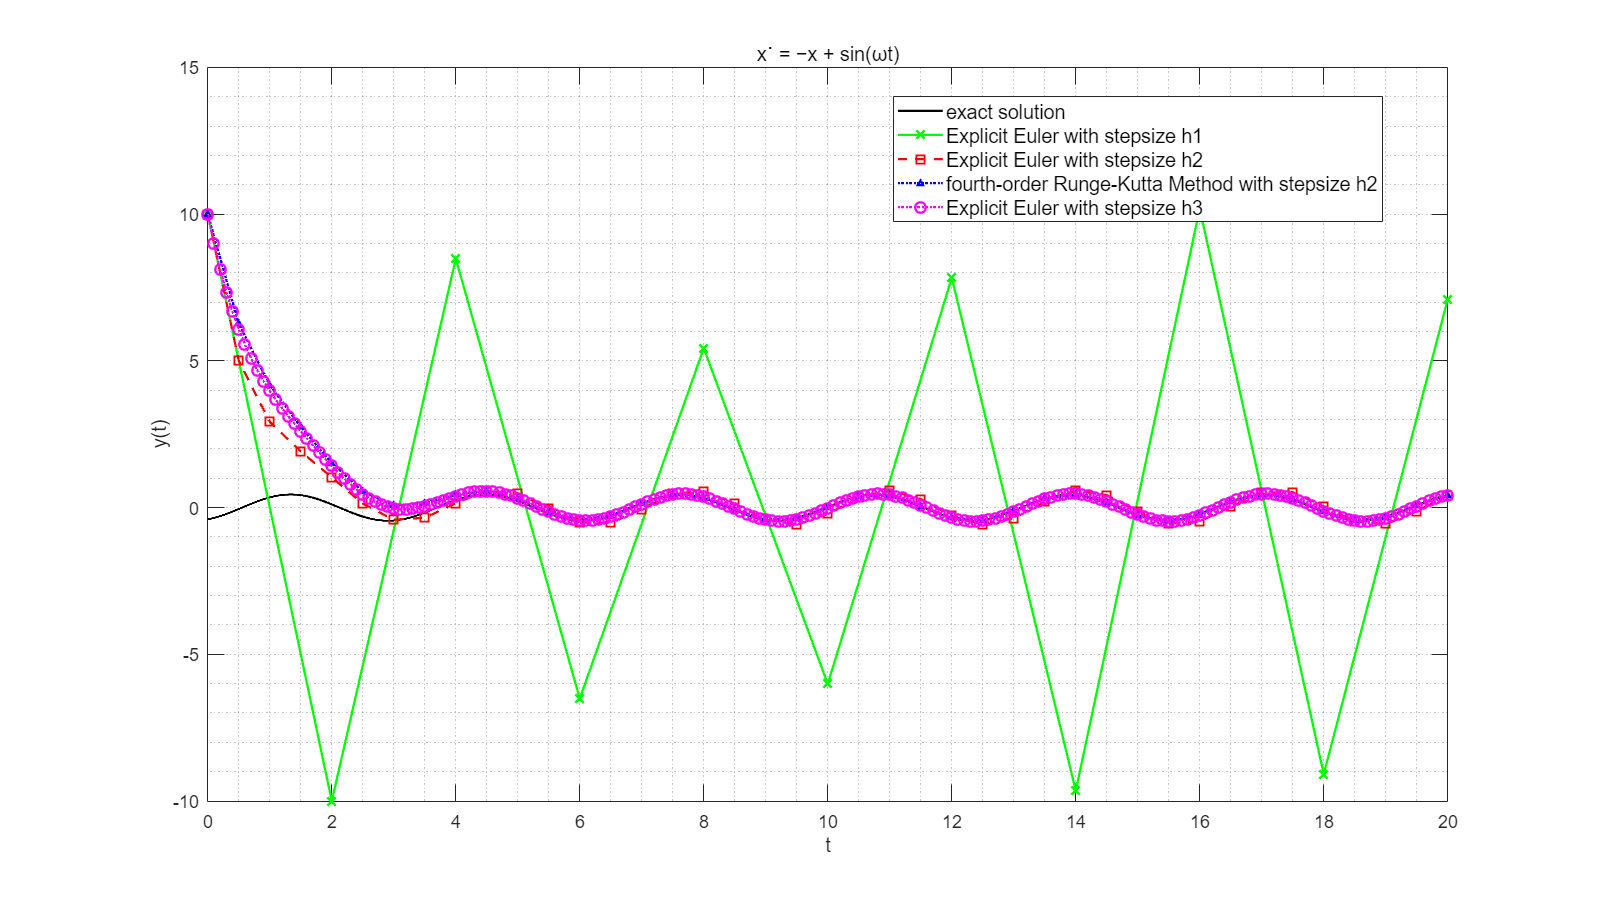

% Housekeeping
clear
clc

% Define the basic parameters
x0 = 10;   % define the initial condition
omg = 2;   % define the Omega
t0 = 0;    % define the initial time
tf = 20;   % define the final time
h1 = 2;    % define the stepsize 1
h2 = 0.5;  % define the stepsize 2
h3 = 0.1;  % define the stepsize 3

% Define the function f
f = @(x,t) -x + sin(omg * t);

% Compute the exact solution
t = t0 : 0.001 : tf; % define the t for exact solution
x = (1 / (1 + omg ^ 2)) * (sin(omg * t) - omg * cos(omg * t));

% Compute the numerical solution
t1 = t0 : h1 : tf; % define the t for h1
t2 = t0 : h2 : tf; % define the t for h2
t3 = t0 : h3 : tf; % define the t for h3

x1 = zeros(1, length(t1)); % create empty matrix to store data for Explicit h1
x2 = zeros(1, length(t2)); % create empty matrix to store data for Explicit h2
x3 = x2;                   % create empty matrix to store data for Runge-Kutta
x4 = zeros(1, length(t3)); % create empty matrix to store data for Explicit h3

x1(1) = x0; % define the starting point for x1
x2(1) = x0; % define the starting point for x2
x3(1) = x0; % define the starting point for x3
x4(1) = x0; % define the starting point for x4

for i = 1 : length(t1) - 1

    x1(i + 1) = x1(i) + h1 * f(x1(i), t1(i)); % calculate Explicit Euler for h1

end

for i = 1 : length(t2) - 1

    x2(i + 1) = x2(i) + h2 * f(x2(i), t2(i)); % calculate Explicit Euler for h2

end

for i = 1 : length(t2) - 1

    k1(i) = h2 * f(x3(i), t2(i));
    k2(i) = h2 * f(x3(i) + k1(i) / 2, t2(i) + h2 / 2);
    k3(i) = h2 * f(x3(i) + k2(i) / 2, t2(i) + h2 / 2);
    k4(i) = h2 * f(x3(i) + k3(i), t2(i) + h2);
    x3(i + 1) = x3(i) + (1 / 6) * k1(i) +...
        (1 / 3) * (k2(i) + k3(i)) + (1 / 6) * k4(i); % calculate fourth-order Runge-Kutta

end

for i = 1 : length(t3) - 1

    x4(i + 1) = x4(i) + h3 * f(x4(i), t3(i)); % calculate Explicit Euler for h3

end

% Plot the numerical solutions and compare with the exact solution
plot(t, x, 'k', LineWidth = 1.5);                      % plot exact solution 
hold on
plot(t1, x1, '-xg', LineWidth = 1.5, MarkerSize = 8);  % plot Explicit Euler with stepsize h1
hold on
plot(t2, x2, '--sr', LineWidth = 1.5, MarkerSize = 7); % plot Explicit Euler with stepsize h2
hold on
plot(t2, x3, ':^b', LineWidth = 1.5, MarkerSize = 3);  % plot fourth-order Runge-Kutta Method with stepsize h2
hold on
plot(t3, x4, ':om', LineWidth = 1.5, MarkerSize = 7);  % plot Explicit Euler with stepsize h3
hold off

title('x˙ = −x + sin(ωt)', FontSize = 15);
legend('exact solution', 'Explicit Euler with stepsize h1', 'Explicit Euler with stepsize h2', ...
    'fourth-order Runge-Kutta Method with stepsize h2', 'Explicit Euler with stepsize h3', ...
    'Location', 'Best', FontSize = 13)

xlabel('t'); 
ylabel('y(t)');
set(gca, 'FontSize', 12) % set the fontsize of the axis

grid minor; % set the grid of the graph

% The accuracy of the Explicit Euler increase with the decrease of the
% stepsize, when stepsize is 2, Explicit Euler gives an unstable numerical
% scheme. The accuracy of the fourth-order Runge-Kutta method is better
% than the Explicit Euler with same stepsize.

5. Suppose now the parameter ω is increased. How does this impact the selection of the step size h of a numerical solution? (You may wish to see this in practice, by experimenting with different values of λ and h in your code.)

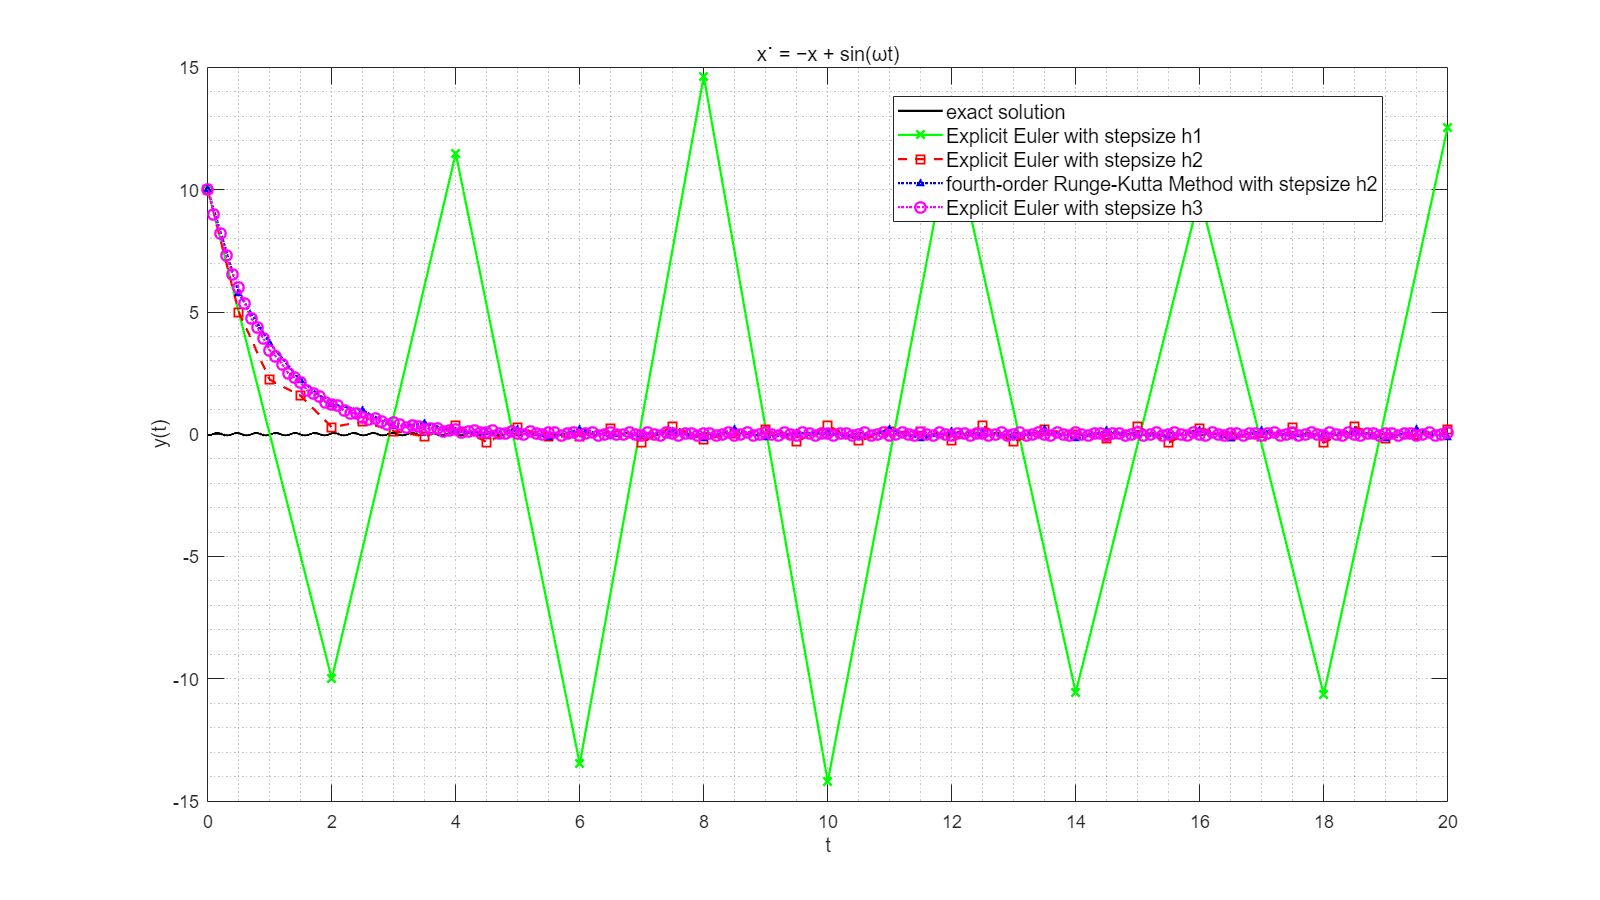

% Housekeeping
clear
clc

% Define the basic parameters
x0 = 10;   % define the initial condition
omg = 20;   % define the Omega
t0 = 0;    % define the initial time
tf = 20;   % define the final time
h1 = 2;    % define the stepsize 1
h2 = 0.5;  % define the stepsize 2
h3 = 0.1;  % define the stepsize 3

% Define the function f
f = @(x,t) -x + sin(omg * t);

% Compute the exact solution
t = t0 : 0.001 : tf; % define the t for exact solution
xr = (1 / (1 + omg ^ 2)) * (sin(omg * t) - omg * cos(omg * t));

% Compute the numerical solution
t1 = t0 : h1 : tf; % define the t for h1
t2 = t0 : h2 : tf; % define the t for h2
t3 = t0 : h3 : tf; % define the t for h3

x1 = zeros(1, length(t1)); % create empty matrix to store data for Explicit h1
x2 = zeros(1, length(t2)); % create empty matrix to store data for Explicit h2
x3 = x2;                   % create empty matrix to store data for Runge-Kutta
k1 = x2;                   % create empty matrix to store data for Runge-Kutta
k2 = x2;                   % create empty matrix to store data for Runge-Kutta
k3 = x2;                   % create empty matrix to store data for Runge-Kutta
k4 = x2;                   % create empty matrix to store data for Runge-Kutta
x4 = zeros(1, length(t3)); % create empty matrix to store data for Explicit h3

x1(1) = x0; % define the starting point for x1
x2(1) = x0; % define the starting point for x2
x3(1) = x0; % define the starting point for x3
x4(1) = x0; % define the starting point for x4

for i = 1 : length(t1) - 1

    x1(i + 1) = x1(i) + h1 * f(x1(i), t1(i)); % calculate Explicit Euler for h1

end

for i = 1 : length(t2) - 1

    x2(i + 1) = x2(i) + h2 * f(x2(i), t2(i)); % calculate Explicit Euler for h2

end

for i = 1 : length(t2) - 1

    k1(i) = h2 * f(x3(i), t2(i));
    k2(i) = h2 * f(x3(i) + k1(i) / 2, t2(i) + h2 / 2);
    k3(i) = h2 * f(x3(i) + k2(i) / 2, t2(i) + h2 / 2);
    k4(i) = h2 * f(x3(i) + k3(i), t2(i) + h2);
    x3(i + 1) = x3(i) + (1 / 6) * k1(i) +...
        (1 / 3) * (k2(i) + k3(i)) + (1 / 6) * k4(i); % calculate fourth-order Runge-Kutta

end

for i = 1 : length(t3) - 1

    x4(i + 1) = x4(i) + h3 * f(x4(i), t3(i)); % calculate Explicit Euler for h3

end

% Plot the numerical solutions and compare with the exact solution
plot(t, xr, 'k', LineWidth = 1.5);                     % plot exact solution 
hold on
plot(t1, x1, '-xg', LineWidth = 1.5, MarkerSize = 8);  % plot Explicit Euler with stepsize h1
hold on
plot(t2, x2, '--sr', LineWidth = 1.5, MarkerSize = 7); % plot Explicit Euler with stepsize h2
hold on
plot(t2, x3, ':^b', LineWidth = 1.5, MarkerSize = 3);  % plot fourth-order Runge-Kutta Method with stepsize h2
hold on
plot(t3, x4, ':om', LineWidth = 1.5, MarkerSize = 7);  % plot Explicit Euler with stepsize h3
hold off

title('x˙ = −x + sin(ωt)', FontSize = 15);
legend('exact solution', 'Explicit Euler with stepsize h1', 'Explicit Euler with stepsize h2', ...
    'fourth-order Runge-Kutta Method with stepsize h2', 'Explicit Euler with stepsize h3', ...
    'Location', 'Best', FontSize = 13)

xlabel('t'); 
ylabel('y(t)');
set(gca, 'FontSize', 12) % set the fontsize of the axis

grid minor; % set the grid of the graph

% Increasing in the parameter ω results smaller stepsize required for
% numerical solution to maintain same level of accuracy, as the wavelegth
% of the solution fall.

#### Exercise 5 (An example using the trapezoidal method)

The RC circuit shown in Figure 1 has input voltage Vin(t). The voltage across the capacitor is the output voltage Vout(t). For a given input voltage, the output voltage is the solution of the differential equation

dVout / dt + Vout / RC = Vin / RC.

Let R = 100 kΩ and C = 100μF. Using either your own code or the code provided, use the trapezoidal method to obtain a numerical solution for the output Vout(t) given the input

Vin = sin(t) + 0.5sin(400t) .

Experiment with different step sizes.

Note that you can use an in-built solver, e.g. ”fsolve”, to obtain the solution of the algebraic equation required at each time step.

% Housekeeping
clear
clc

% Define the basic parameters
V0 = 10;   % define the initial condition
t0 = 0;    % define the initial time
tf = 50;   % define the final time
h1 = 0.1;  % define the stepsize 1
h2 = 1;    % define the stepsize 2
h3 = 10;   % define the stepsize 3

% Define the function f
f = @(V,t) -V / 10 + sin(t) / 10 + sin(400 * t) / (2 * 10);

% Compute the exact solution
t = t0 : 0.001 : tf; % define the t for exact solution

syms tr;
fr = dsolve('DV = -V / 10 + sin(tr) / 10 + sin(400 * tr) / (2 * 10)', 'V(0)=10', 'tr');

Vr = subs(fr,tr,t);  % sub t into the solution
Vr = double(Vr);     % transform syms to double

% Compute the numerical solution
t1 = t0 : h1 : tf; % define the t for h1
t2 = t0 : h2 : tf; % define the t for h2
t3 = t0 : h3 : tf; % define the t for h3

V1 = zeros(1, length(t1)); % create empty matrix to store data for Trapezoidal h1
V2 = zeros(1, length(t2)); % create empty matrix to store data for Trapezoidal h2
V3 = zeros(1, length(t3)); % create empty matrix to store data for Trapezoidal h3

V1(1) = V0; % define the starting point for x1
V2(1) = V0; % define the starting point for x2
V3(1) = V0; % define the starting point for x3

for i = 1 : length(t1) - 1

    ftrap1 = @(Vnext1) V1(i) + (h1 / 2) * (f(Vnext1, t1(i + 1)) + f(V1(i), t1(i))) - Vnext1;
    V1(i + 1) = fsolve(ftrap1, V1(i)); % calculate Trapezoidal Method for h1

end


方程已解。

fsolve 已完成，因为按照函数容差的值衡量，
函数值向量接近于零，并且按照梯度的值衡量，
问题似乎为正则问题。

<停止条件详细信息>

方程已解。

fsolve 已完成，因为按照函数容差的值衡量，
函数值向量接近于零，并且按照梯度的值衡量，
问题似乎为正则问题。

<停止条件详细信息>




for i = 1 : length(t2) - 1

    ftrap2 = @(Vnext2) V2(i) + (h2 / 2) * (f(Vnext2, t2(i + 1)) + f(V2(i), t2(i))) - Vnext2;
    V2(i + 1) = fsolve(ftrap2, V2(i)); % calculate Trapezoidal Method for h2

end


方程已解。

fsolve 已完成，因为按照函数容差的值衡量，
函数值向量接近于零，并且按照梯度的值衡量，
问题似乎为正则问题。

<停止条件详细信息>

方程已解。

fsolve 已完成，因为按照函数容差的值衡量，
函数值向量接近于零，并且按照梯度的值衡量，
问题似乎为正则问题。

<停止条件详细信息>




for i = 1 : length(t3) - 1

    ftrap3 = @(Vnext3) V3(i) + (h3 / 2) * (f(Vnext3, t3(i + 1)) + f(V3(i), t3(i))) - Vnext3;
    V3(i + 1) = fsolve(ftrap3, V3(i)); % calculate Trapezoidal Method for h3

end


方程已解。

fsolve 已完成，因为按照函数容差的值衡量，
函数值向量接近于零，并且按照梯度的值衡量，
问题似乎为正则问题。

<停止条件详细信息>

方程已解。

fsolve 已完成，因为按照函数容差的值衡量，
函数值向量接近于零，并且按照梯度的值衡量，
问题似乎为正则问题。

<停止条件详细信息>



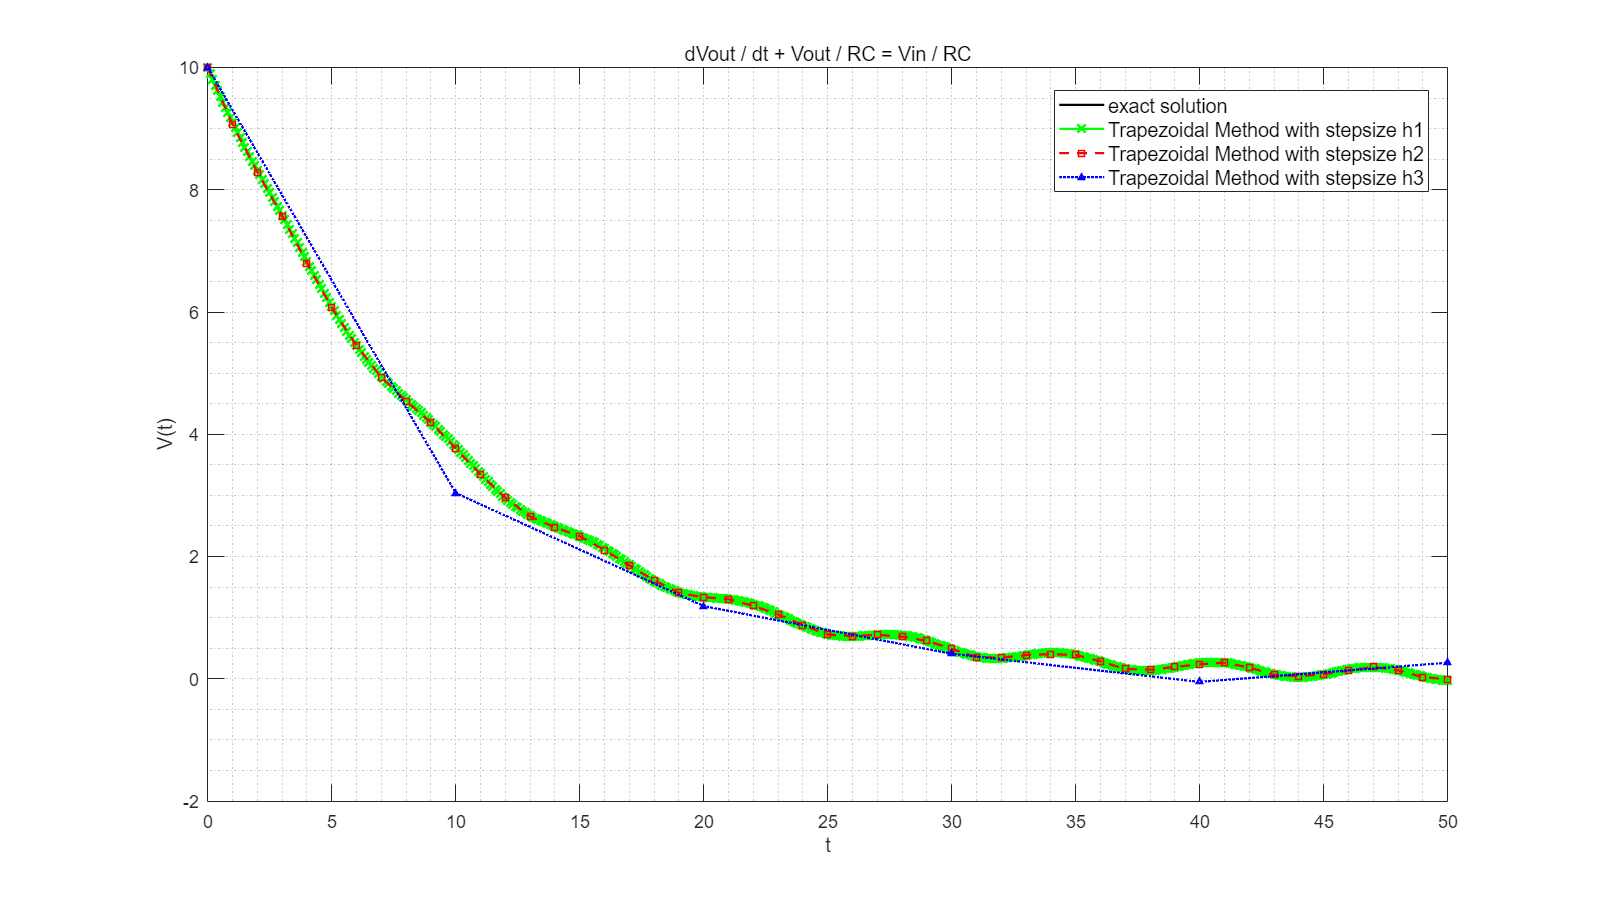


% Plot the numerical solutions and compare with the exact solution
plot(t, Vr, 'k', LineWidth = 1.5);                     % plot exact solution 
hold on
plot(t1, V1, '-xg', LineWidth = 1.5, MarkerSize = 8);  % plot Trapezoidal Method with stepsize h1
hold on
plot(t2, V2, '--sr', LineWidth = 1.5, MarkerSize = 5); % plot Trapezoidal Method with stepsize h2
hold on
plot(t3, V3, ':^b', LineWidth = 1.5, MarkerSize = 3);  % plot Trapezoidal Method with stepsize h3
hold off

title('dVout / dt + Vout / RC = Vin / RC', FontSize = 15);
legend('exact solution', 'Trapezoidal Method with stepsize h1', 'Trapezoidal Method with stepsize h2', ...
    'Trapezoidal Method with stepsize h3', 'Location', 'Best', FontSize = 13)

xlabel('t'); 
ylabel('V(t)');
set(gca, 'FontSize', 12) % set the fontsize of the axis

grid minor;                            % set the grid of the graph

#### Exercise 6 (The simple harmonic oscillator - a second order ODE)

A simple harmonic oscillator is described by a second order ODE of the form

mx′′ + kx = 0 ,

where k and m are (scalar) constants. Defining the vector y = [ x; x′ ] , the second order ODE can be written as the system of first ODEs

y′ = [ 0 1; -k / m 0 ] y = Ay  .

Suppose the constant parameters are such that k = m.

1. Compute the egeinvalues and the normalized eigenvectors of the matrix A.

% for k=m

% Housekeeping
clear
clc

% Define the matrix A
A = [ 0 1; -1 0 ];

% Compute the eigenvectors and egeinvalues
[eivA eigA] = eig(A)

eivA =    0.7071 + 0.0000i   0.7071 + 0.0000i
   0.0000 + 0.7071i   0.0000 - 0.7071i


eigA =    0.0000 + 1.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 - 1.0000i


2. Let Λ denote the diagonal matrix with the eigenvalues of A on its diagonal and let P denote the matrix with columns corresponding to the eigenvectors of A. Define the new vector

z = [ x ; x′ ] = P^−1 y .

Show that

z′ = Λz .

% Define the value of P
P = eivA;

% z' = P^-1 y' =  P^-1 A y' =  P^-1 P Λ P^-1 y' = Λ z

3. If the initial conditions are x(0) = x0 and x′(0) = xd, what are the corresponding initial conditions for y(0) and z(0)?

% z(0) = [ x0 ; xd ]
% y(0) = Pz(0)

4. The ODE defined in terms of z essentially consists of two decoupled first order linear differential equations. Select an appropriate scheme and obtain the numerical solutions which approximate z1(t) and z2(t) (where z1 and z2 are the two components of z.

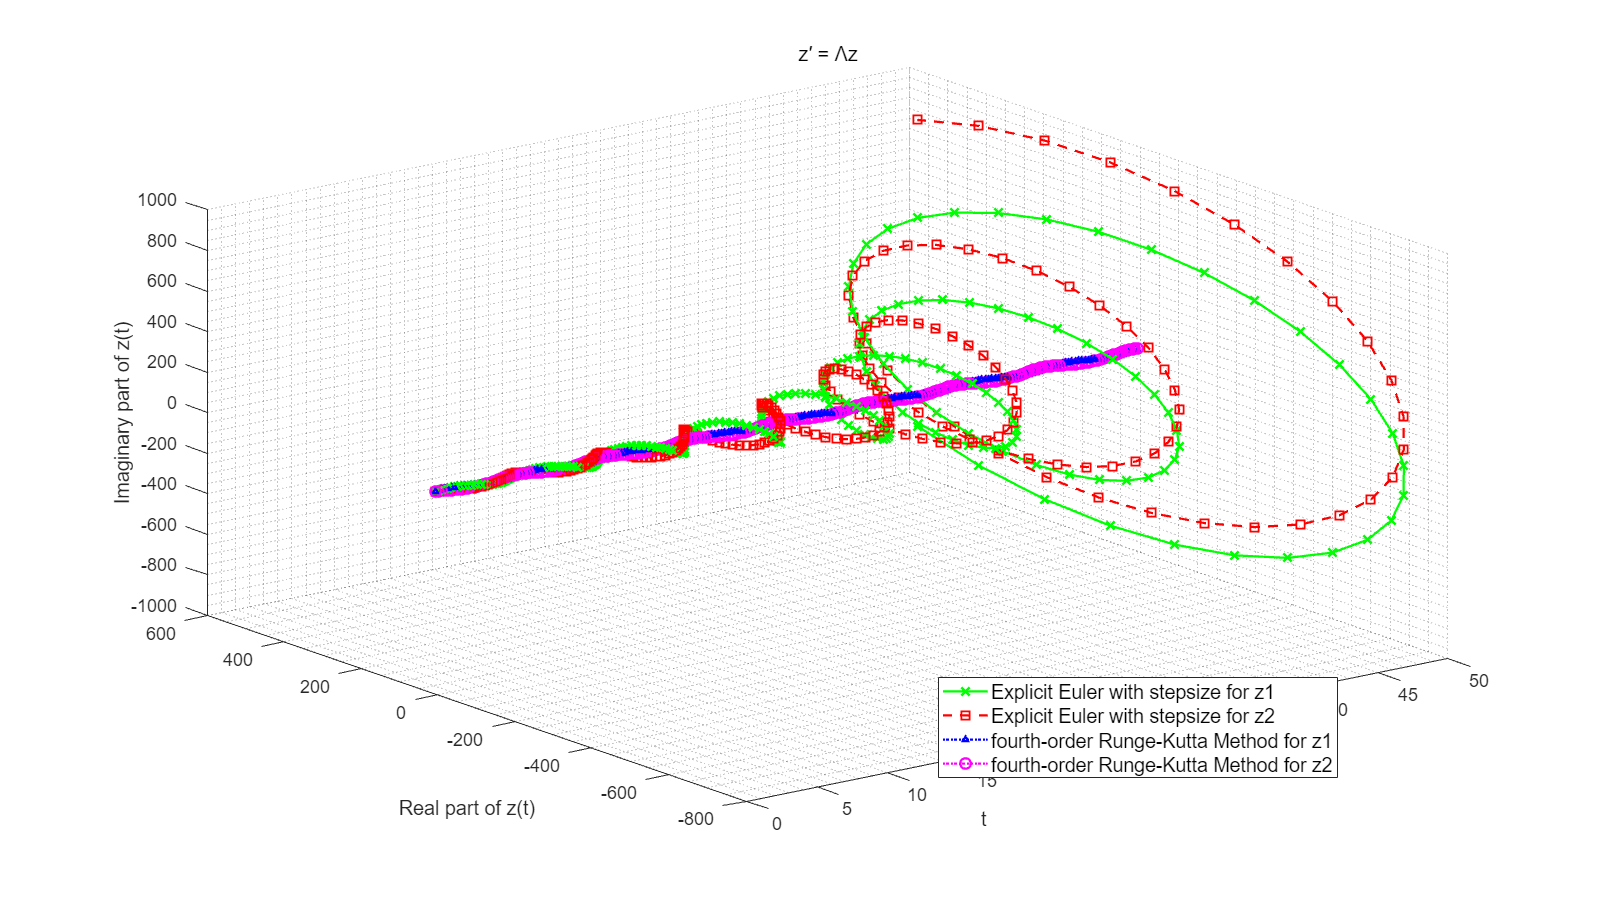

% Define the basic parameters
y0 = [10; 0];      % define the initial condition
z0 = inv(P)*y0;    % define the initial condition of z
eig1 = eigA(1, 1); % define the λ1
eig2 = eigA(2, 2); % define the λ2
t0 = 0;    % define the initial time
tf = 50;   % define the final time
h = 0.2;  % define the stepsize

% Define the function f
f1 = @(z) eig1*z;
f2 = @(z) eig2*z;

% Compute the numerical solution
t = t0 : h : tf; % define the t for h

z1 = zeros(1, length(t)); % create empty matrix to store data for Explicit z1
z2 = z1;                  % create empty matrix to store data for Explicit z2
z3 = z1;                  % create empty matrix to store data for Runge-Kutta z1
x3 = z1;                  % create empty matrix to store data for Runge-Kutta z2

k11 = z1;                 % create empty matrix to store data for Runge-Kutta z1
k12 = z1;                 % create empty matrix to store data for Runge-Kutta z1
k13 = z1;                 % create empty matrix to store data for Runge-Kutta z1
k14 = z1;                 % create empty matrix to store data for Runge-Kutta z1

k21 = z1;                 % create empty matrix to store data for Runge-Kutta z2
k22 = z1;                 % create empty matrix to store data for Runge-Kutta z2
k23 = z1;                 % create empty matrix to store data for Runge-Kutta z2
k24 = z1;                 % create empty matrix to store data for Runge-Kutta z2


z1(1) = z0(1); % define the starting point for z1
z2(1) = z0(2); % define the starting point for z2
z3(1) = z0(1); % define the starting point for z3
z4(1) = z0(2); % define the starting point for z4

for i = 1 : length(t) - 1

    z1(i + 1) = z1(i) + h * f1(z1(i)); % calculate Explicit Euler for z1

end                        

for i = 1 : length(t) - 1

    z2(i + 1) = z2(i) + h * f2(z2(i)); % calculate Explicit Euler for z2

end

for i = 1 : length(t) - 1

    k11(i) = h * f1(z3(i));
    k12(i) = h * f1(z3(i) + k11(i) / 2);
    k13(i) = h * f1(z3(i) + k12(i) / 2);
    k14(i) = h * f1(z3(i) + k13(i));
    z3(i + 1) = z3(i) + (1 / 6) * k11(i) +...
        (1 / 3) * (k12(i) + k13(i)) + (1 / 6) * k14(i); % calculate fourth-order Runge-Kutta for z1

end

for i = 1 : length(t) - 1

    k21(i) = h * f2(z4(i));
    k22(i) = h * f2(z4(i) + k21(i) / 2);
    k23(i) = h * f2(z4(i) + k22(i) / 2);
    k24(i) = h * f2(z4(i) + k23(i));
    z4(i + 1) = z4(i) + (1 / 6) * k21(i) +...
        (1 / 3) * (k22(i) + k23(i)) + (1 / 6) * k24(i); % calculate fourth-order Runge-Kutta for z2

end

% Plot the numerical solutions
plot3(t, real(z1), imag(z1), '-xg', LineWidth = 1.5, MarkerSize = 8);  % plot Explicit Euler for z1
hold on
plot3(t, real(z2), imag(z2), '--sr', LineWidth = 1.5, MarkerSize = 7); % plot Explicit Euler for z2
hold on
plot3(t, real(z3), imag(z3), ':^b', LineWidth = 1.5, MarkerSize = 3);  % plot fourth-order Runge-Kutta Method for z1
hold on
plot3(t, real(z4), imag(z4), ':om', LineWidth = 1.5, MarkerSize = 7);  % plot fourth-order Runge-Kutta Method for z2
hold off

title('z′ = Λz', FontSize = 15);
legend('Explicit Euler with stepsize for z1', 'Explicit Euler with stepsize for z2', ...
    'fourth-order Runge-Kutta Method for z1', 'fourth-order Runge-Kutta Method for z2', ...
    'Location', 'Best', FontSize = 13)

xlabel('t'); 
ylabel('Real part of z(t)');
zlabel('Imaginary part of z(t)');
set(gca, 'FontSize', 12) % set the fontsize of the axis

grid minor; % set the grid of the graph

5. Using the numerical solution obtained in part 4. of this exercise construct a numerical solution for y(t).

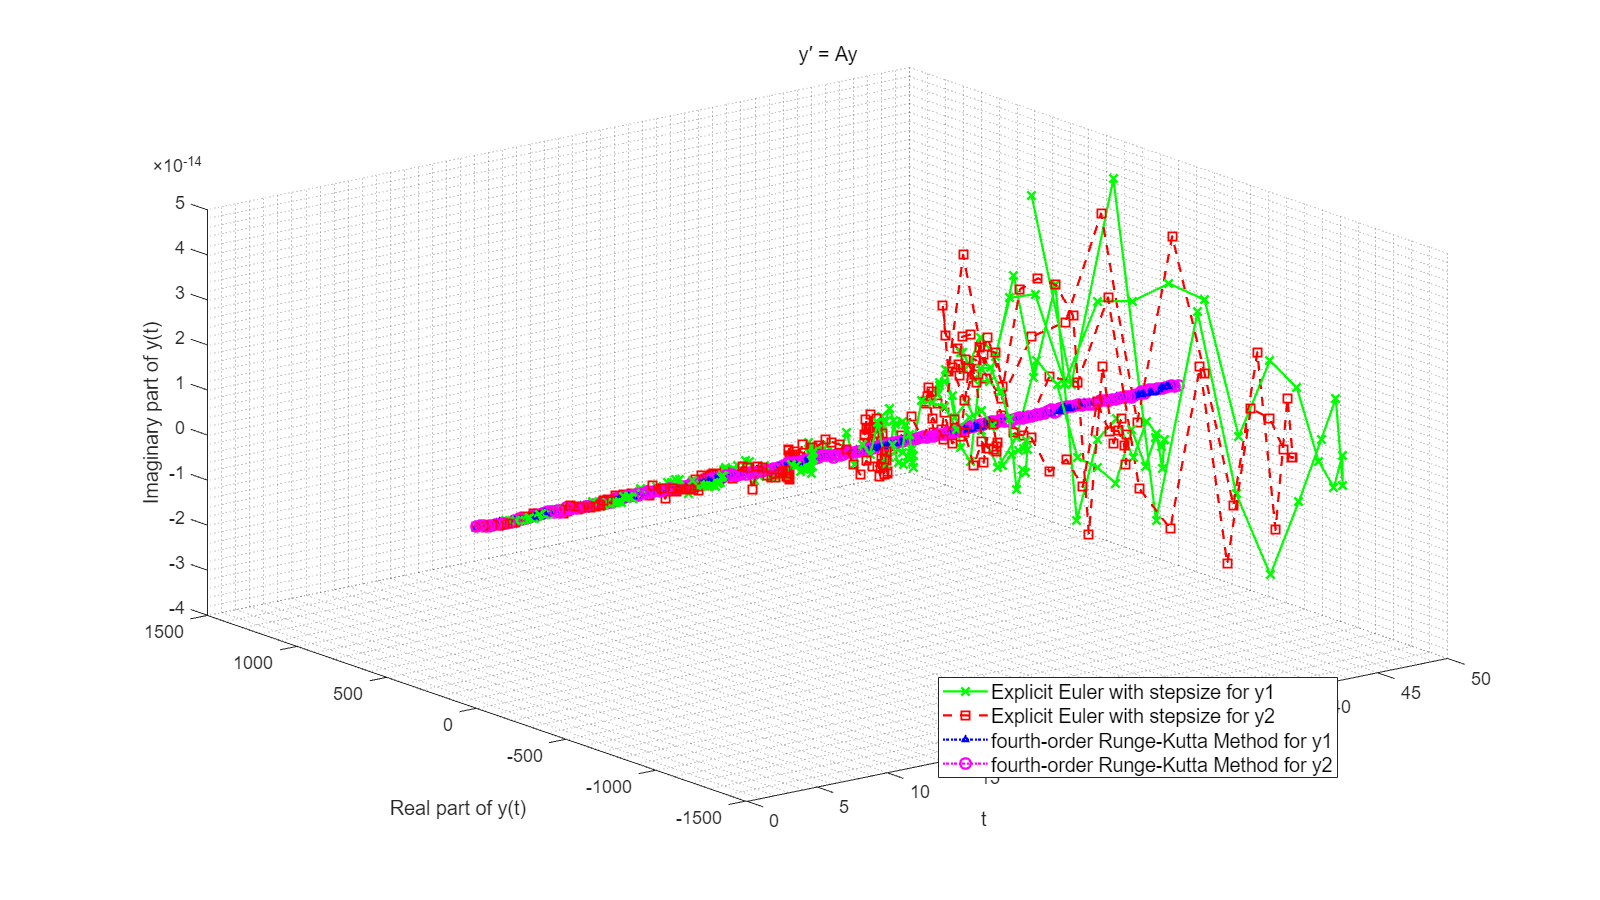

% y = Pz
Y12 = P*[z1 ; z2]; % find solution for Explicit Euler
y1 = Y12(1 , :);
y2 = Y12(2 , :);

Y34 = P*[z3 ; z4]; % find solution for fourth-order Runge-Kutta Method
y3 = Y34(1 , :);
y4 = Y34(2 , :);

% Plot the numerical solutions
plot3(t, real(y1), imag(y1), '-xg', LineWidth = 1.5, MarkerSize = 8);  % plot Explicit Euler for y1
hold on
plot3(t, real(y2), imag(y2), '--sr', LineWidth = 1.5, MarkerSize = 7); % plot Explicit Euler for y2
hold on
plot3(t, real(y3), imag(y3), ':^b', LineWidth = 1.5, MarkerSize = 3);  % plot fourth-order Runge-Kutta Method for y1
hold on
plot3(t, real(y4), imag(y4), ':om', LineWidth = 1.5, MarkerSize = 7);  % plot fourth-order Runge-Kutta Method for y2
hold off

title('y′ = Ay', FontSize = 15);
legend('Explicit Euler with stepsize for y1', 'Explicit Euler with stepsize for y2', ...
    'fourth-order Runge-Kutta Method for y1', 'fourth-order Runge-Kutta Method for y2', ...
    'Location', 'Best', FontSize = 13)

xlabel('t'); 
ylabel('Real part of y(t)');
zlabel('Imaginary part of y(t)');
set(gca, 'FontSize', 12) % set the fontsize of the axis

grid minor; % set the grid of the graph

### Part II: Theoretical Considerations

#### Exercise 7 (Trapezoidal Method - Linearization)

Consider the Trapezoidal method for obtaining a numerical solution of the initial value problem

y′ = f(t, y) , y(0) = y0 .

In general, this multi-step method requires solving a nonlinear algebraic equation at each time step.

1. Compute the linearization of f(tn+1, yn+1) about yn.

2. Show that applying the trapezoidal method to the linearized problem ( i.e. when f(tn+1, yn+1) is replaced with the linearization computed in part 1. of this exercise) results in a numerical solution with the same order of accuracy achieved when applying the trapezoidal method to the original (nonlinear) problem.